%==========================================================================
% Main script for weather data processing and PV performance analysis
%
% This script:
%   - Imports and cleans weather data for the last three years
%   - Imports station coordinates and plots them on a map
%   - Performs sunshine duration analysis per station and per year
%   - Computes EPOA and PV cell temperature
%   - Computes PV efficiency using a MEX function (pv_efficiency.c)
%
% Required files/functions:
%   - function_clean_data.m
%   - function_EPOA.m
%   - function_Tcell.m
%   - pv_efficiency.c (MEX source)
%   - coordonnees_stations.csv
%==========================================================================

clear; clc; close all;

% Part 1 : Import and clean the data
fprintf('-------------------- Part 1 : Import and clean the data --------------------\n');

-------------------- Part 1 : Import and clean the data --------------------



% Load and clean data from the last 3 years 
fprintf('...Loading and cleaning weather data...\n');

...Loading and cleaning weather data...


[cleaned_data_2024, cleaned_data_2023, cleaned_data_2022] = function_clean_data();

% Importing station coordinates
fprintf('...Importing station coordinates...\n');

...Importing station coordinates...



filename = 'coordonnees_stations.csv';
opts = detectImportOptions(filename, 'Delimiter',';', 'VariableNamingRule','preserve');
T = readtable(filename, opts);

% Part 2 : Map of stations
fprintf('-------------------- Part 2 : Map of stations --------------------\n');

-------------------- Part 2 : Map of stations --------------------


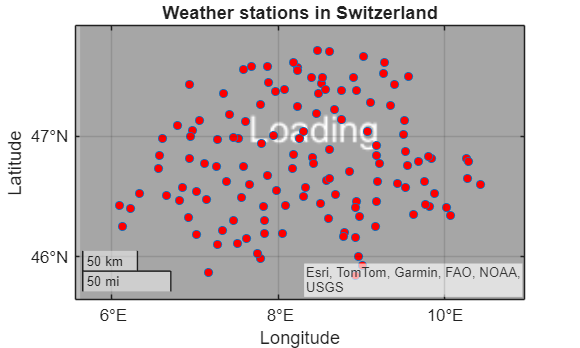


% Extract relevant columns from the coordinate table
altitude = T.('Hauteur de mesure m s. mer');    % station altitude [m]
lat = T.Latitude;                               % latitude  [deg]
lon = T.Longitude;                              % longitude [deg]
abreviation = string(T.('Abr.'));               % station abbreviation

% Create the figure and the map centered on Switzerland
figure
gx = geoaxes; 
geobasemap(gx,'topographic'); 
hold on

% Add station points
p = geoplot(gx, lat, lon, 'o', 'MarkerFaceColor','r', 'MarkerSize',5);
title('Weather stations in Switzerland')

% Define the information to display in data tips
p.DataTipTemplate.DataTipRows = [ ...
    dataTipTextRow('Abreviation', abreviation), ...
    dataTipTextRow('Altitude (m)', altitude), ...
    dataTipTextRow('Latitude', lat), ...
    dataTipTextRow('Longitude', lon)];

% Center the map around the stations
geolimits(gx, [min(lat)-0.2 max(lat)+0.2], [min(lon)-0.2 max(lon)+0.2])

% Part 3 : Sunshine analysis
fprintf('-------------------- Part 3 : Sunshine analysis --------------------\n');

-------------------- Part 3 : Sunshine analysis --------------------


% Part 3.1 : Average duration of sunshine 
fprintf('-------------------- Part 3.1 : Average duration of sunshine --------------------\n');

-------------------- Part 3.1 : Average duration of sunshine --------------------



Analysis for 2024 :



The sunniest station : OTL (10313 min)


Least sunny station : ELM (5174 min)


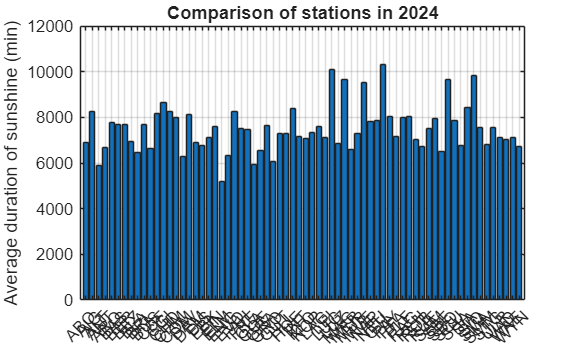


Analysis for 2023 :



The sunniest station : OTL (11726 min)


Least sunny station : ELM (6050 min)


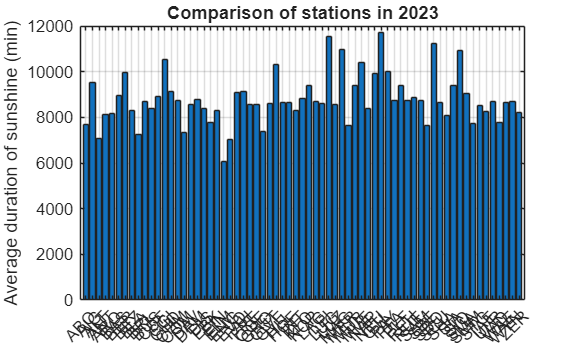


Analysis for 2022 :



The sunniest station : OTL (12887 min)


Least sunny station : ELM (6815 min)


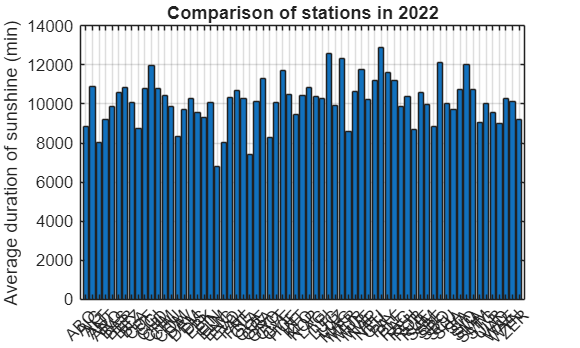


years = [2024, 2023, 2022];
cleaned_sets = {cleaned_data_2024, cleaned_data_2023, cleaned_data_2022};

for a = 1:numel(years)
    target_year = years(a);
    cleaned_data = cleaned_sets{a};

    fprintf('\nAnalysis for %d :\n', target_year);

    
    % Concatenate all station monthly tables into one global table
    % This allows computing overall statistics across stations for the given year.
    all_data = vertcat(cleaned_data{:});

    dates = all_data.Date;                 % timestamps (monthly records)
    sunshine_min = all_data.sre000m0;      % sunshine duration [min]
    sunshine_percent = all_data.sremaxmv;  % relative sunshine [%]

     % Build a year-month index to compute monthly averages across all stations
    year_month = datetime(year(dates), month(dates), 1);
    [unique_months, ~, month_idx] = unique(year_month);

    % Monthly mean sunshine duration across all stations 
    monthly_min = accumarray(month_idx, sunshine_min, [], @mean);
    monthly_percent = accumarray(month_idx, sunshine_percent, [], @mean);

    % Store monthly averages in a compact table 
    monthly_avg = table(unique_months, monthly_min, monthly_percent, ...
        'VariableNames', {'Date', 'mean_sre000m0', 'mean_sremaxmv'});
    monthly_avg = sortrows(monthly_avg, 'Date');

    % Global comparison between stations 
    % For each station, compute the mean sunshine duration over the 12 months of the year.
    station_names = all_data{:,1};           % station identifiers (first column)
    sre000m0_values = all_data.sre000m0;     % sunshine duration [min]
    tbl = table(station_names, sre000m0_values);
    station_avg = varfun(@mean, tbl, 'InputVariables','sre000m0_values', ...
        'GroupingVariables','station_names');

    % Identify the most and least sunny stations for the considered year
    [~, idxMax] = max(station_avg.mean_sre000m0_values);
    [~, idxMin] = min(station_avg.mean_sre000m0_values);

    fprintf('\nThe sunniest station : %s (%.0f min)\n', ...
        char(station_avg.station_names(idxMax)), station_avg.mean_sre000m0_values(idxMax));
    fprintf('Least sunny station : %s (%.0f min)\n', ...
        char(station_avg.station_names(idxMin)), station_avg.mean_sre000m0_values(idxMin));

    % Bar chart for station comparison (mean annual sunshine duration per station)
    figure('Name', ['Station comparison ' num2str(target_year)], 'NumberTitle', 'off');
    bar(categorical(station_avg.station_names), station_avg.mean_sre000m0_values);
    xtickangle(45);
    ylabel('Average duration of sunshine (min)');
    title(['Comparison of stations in ' num2str(target_year)]);
    grid on;
end

% Part 3.2 + 3.3 : Stability + Best trade-off
fprintf('-------------------- Part 3.2/3.3 : Stability + Trade-off --------------------\n');

-------------------- Part 3.2/3.3 : Stability + Trade-off --------------------



for a = 1:numel(years)
    target_year  = years(a);
    cleaned_data = cleaned_sets{a};

    fprintf('\nAnalysis for %d :\n', target_year);
    
    % Concatenate all station monthly tables into one global table
    % This allows computing overall statistics across stations for the given year.
    all_data = vertcat(cleaned_data{:});
    station_names = all_data{:,1};      % station identifiers
    sre000m0_values = all_data.sre000m0;  % sunshine duration [min]
    tbl = table(station_names, sre000m0_values);

    % Compute per-station statistics over the 12 months of the year
    % mean: average annual sunshine
    % std: dispersion of monthly sunshine values (standard deviation)
    S = varfun(@mean, tbl, 'InputVariables','sre000m0_values', 'GroupingVariables','station_names');
    S = join(S, varfun(@std,  tbl, 'InputVariables','sre000m0_values', 'GroupingVariables','station_names'));

    % CV = Coefficient of Variation = std / mean
    % A low CV indicates a more homogeneous distribution of sunshine over the year
    S.mean_min = S.mean_sre000m0_values;     % mean annual sunshine (min)
    S.std_min = S.std_sre000m0_values;
    S.cv = S.std_min ./ S.mean_min;    % coefficient of variation (CV)

    % Trade-off metric combining high sunshine and low variability
    S.score = S.mean_min ./ S.cv;         % higher score = sunny and stable station

    % Ranking by stability (lowest CV first)
    Sst = sortrows(S, 'cv', 'ascend');       % ranks stations from most stable to least stable
    fprintf('\nTop 5 most stable stations:\n');
    disp(Sst(1:5, {'station_names','mean_min','std_min','cv'}))

    % Ranking by best trade-off between sunshine and stability
    Ssc = sortrows(S, 'score', 'descend');   % ranks stations from best to least favourable compromise between sunshine and stability
    fprintf('\nTop 5 best trade-off stations (sunshine + stability):\n');
    disp(Ssc(1:5, {'station_names','mean_min','cv','score'}))
end


Analysis for 2024 :



Top 5 most stable stations:


    station_names    mean_min    std_min      cv   
    _____________    ________    _______    _______

       {'DAV'}        8113.1     2324.7     0.28653
       {'NAP'}        7806.5     2421.9     0.31024
       {'MVE'}        9511.6     3201.4     0.33658
       {'EVO'}        8245.8     2792.3     0.33864
       {'ROB'}        6741.8     2288.9      0.3395




Top 5 best trade-off stations (sunshine + stability):


    station_names    mean_min      cv       score
    _____________    ________    _______    _____

       {'LUG'}         10096     0.34969    28871
       {'OTL'}         10313     0.36191    28497
       {'DAV'}        8113.1     0.28653    28315
       {'MVE'}        9511.6     0.33658    28260
       {'SBO'}        9663.3     0.36998    26119




Analysis for 2023 :



Top 5 most stable stations:


    station_names    mean_min    std_min      cv   
    _____________    ________    _______    _______

       {'SBE'}        7648.7     1905.7     0.24915
       {'SAM'}        8724.5     2211.5     0.25348
       {'OTL'}         11726     3452.9     0.29448
       {'COM'}          7333     2168.6     0.29573
       {'LUG'}         11545     3448.4     0.29869




Top 5 best trade-off stations (sunshine + stability):


    station_names    mean_min      cv       score
    _____________    ________    _______    _____

       {'OTL'}         11726     0.29448    39819
       {'LUG'}         11545     0.29869    38652
       {'SBO'}         11232     0.30294    37077
       {'SAM'}        8724.5     0.25348    34419
       {'SBE'}        7648.7     0.24915    30699




Analysis for 2022 :



Top 5 most stable stations:


    station_names    mean_min    std_min      cv   
    _____________    ________    _______    _______

       {'SBE'}          8824     2244.8      0.2544
       {'SAM'}        9989.9     2829.1      0.2832
       {'OTL'}         12887     3707.3     0.28767
       {'ROB'}        8669.2     2577.9     0.29736
       {'ZER'}        9206.1     2747.3     0.29842




Top 5 best trade-off stations (sunshine + stability):


    station_names    mean_min      cv       score
    _____________    ________    _______    _____

       {'OTL'}         12887     0.28767    44798
       {'LUG'}         12568     0.31064    40458
       {'SBO'}         12122     0.33788    35876
       {'SAM'}        9989.9      0.2832    35276
       {'MVE'}         11780     0.33626    35032



% Part 4 : Calculation of cell temperature
fprintf('-------------------- Part 4 : Calculation of cell temperature --------------------\n');

-------------------- Part 4 : Calculation of cell temperature --------------------



%  Calculation of the EPOA for each year
EPOA_2024 = function_EPOA(cleaned_data_2024, T) ;

Unrecognized function or variable 'pvl_maketimestruct'.

Error in function_EPOA (line 68)
    time = pvl_maketimestruct(datenum(Date), lon);
    ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

EPOA_2023 = function_EPOA(cleaned_data_2023, T);
EPOA_2022 = function_EPOA(cleaned_data_2022, T);

% Calculation of PV cell temperature for each year
Tcell_2024 = function_Tcell(EPOA_2024, cleaned_data_2024);
Tcell_2023 = function_Tcell(EPOA_2023, cleaned_data_2023);
Tcell_2022 = function_Tcell(EPOA_2022, cleaned_data_2022);


fprintf('\nCalculations of EPOA and cell temperature completed for 2024, 2023 and 2022 \n');

% Part 5 : PV efficiency based on cell temperature
fprintf('-------------------- Part 5 : PV efficiency based on cell temperature --------------------\n');

% Compile MEX file
mex pv_efficiency.c

years = [2024, 2023, 2022];
Tcell_sets = {Tcell_2024, Tcell_2023, Tcell_2022};
stations_sets = {
    cellstr(Tcell_2024.Abbreviation_station)
    cellstr(Tcell_2023.Abbreviation_station)
    cellstr(Tcell_2022.Abbreviation_station)
};

% PV model parameters used in the C code (constant for all years)
fprintf('\nPV Efficiency Model Parameters\n');
fprintf('Technology                     : Monocrystalline Silicon (PERC, TOPCon)\n');
fprintf('Reference efficiency (eta_ref) : 21.00 %%\n');
fprintf('Reference temperature (Tref)   : 25.0 °C\n');
fprintf('Temperature coefficient beta   : 0.0045 1/°C\n');
fprintf('Irradiance G                   : 1000 W/m²\n');
fprintf('Panel area A                   : 1 m²\n');

for k = 1:numel(years)
    an = years(k);
    Tab = Tcell_sets{k};

    % Extract relevant columns
    stations = Tab.Abbreviation_station;
    Tmean = Tab.Tcell_annual_mean;

    % Convert to row vectors for C (strings)
    stations_C = strjoin("""" + stations + """", ", ");
    Tmean_C = sprintf('%.4f, ', Tmean);
    Tmean_C(end-1:end) = []; % Remove trailing ", "

    fprintf('\nPV Efficiency Simulation – Year %d\n', an);
    fprintf('Stations (%d):\n', numel(stations));
    fprintf('  %s\n\n', stations_C);
    fprintf('Annual mean cell temperature (°C):\n');
    fprintf('  %s\n\n', Tmean_C);
    fprintf('Output file:\n');
    fprintf('  Efficiency_%d.csv\n\n', an);

    % CSV file name for this year
    filename = sprintf('Efficiency_%d.csv', an);

    % Call the MEX function (sorting + model + CSV export)
    [eta, P, Tcell_sorted, station_sorted] = pv_efficiency(Tmean, stations, filename);

end